clear;clc;

% load parameters
par = importdata('par_scg_bistable.txt');
par = par.data;

% initial values
y0 = zeros(4, 1);
y0(1) = 1;
y0(4) = 0.01;

tmax = 1000;
tspan = 0:0.1:tmax;

[~, y] = ode45(@ODE_SCG, tspan, y0, [], par);

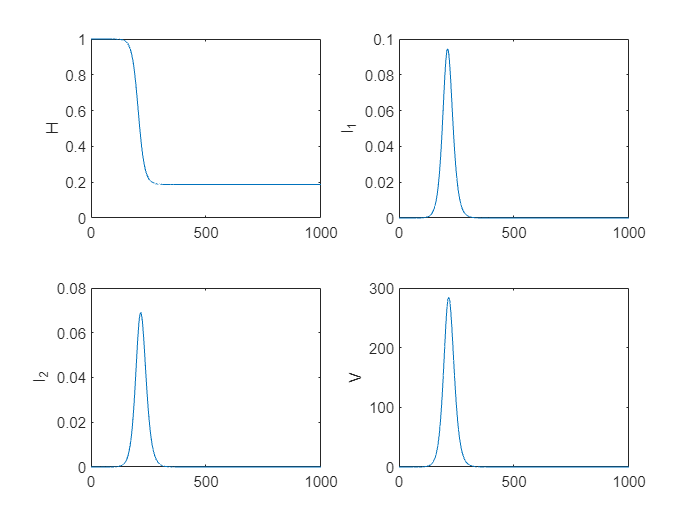

figure;
subplot(2, 2, 1);
plot(tspan, y(:, 1));
ylabel('H');

subplot(2, 2, 2);
plot(tspan, y(:, 2));
ylabel('I_1');

subplot(2, 2, 3);
plot(tspan, y(:, 3));
ylabel('I_2');

subplot(2, 2, 4);
plot(tspan, y(:, 4));
ylabel('V');